***Q4 (c) and Q4 (d) *****MTH739U / MTH739P: Topics in Scientific Computing 2019/20 – Coursework 1 **

**Top Level Summary**

Note - 4 (b) was skipped. This is 4 d) and 4 c)

For this particular question there were many different variables therefore a variable dictionary has been included to cross reference to the question sheet against the coded solution for your convenience:

- 
$$\mathrm{dx}=\Delta x$$


- 
$$\epsilon =\textrm{epsilon}$$


- $h_{\textrm{new}} \;,\;h_{\textrm{old}} =$h_new, h_old respectively

- $M_{\textrm{ij}} =$M

%Q4C Summary of this function goes here
%   Detailed explanation goes here
n = 32;
R = pi;
dx = R/n;
epsilon = double(1/(10^14));
xspan = linspace(0,R,n);
h_exact = sin(xspan)./(xspan);
h_exact(1) = 1;
h_old = ones(1,n);
h_new = ones(1,n);
x= zeros(32);

We generate the following Grid using a loop 1 to n.

Note regarding computation time:

It is required to generate $x_j$ and the same for loop for $x_i$ is used for $x_j$ to save computation time. 


$$x_i =\left(i-\frac{1}{2}\right)\Delta x,i=1,\ldotp \ldotp \ldotp ,n$$


for i = 1:n
    x(1,i) = (i-0.5)*dx;
    x(i,1) = (i-0.5)*dx;
end

M is generated using matrix computation, saving computation time vs multiple loops.


$$M_{i,j} =\Delta x\left(\frac{x_j^2 }{\mathrm{max}\left(x_i ,x_j \right)}-x_j \right)$$


M = dx*(x(:,1).^2./max(x(:,1),x(1,:))-x(:,1));

%h_old = h_old*M;
h_1 = ones(1,n);
k = 1;
l_2 = 1;    %to get into loop
while l_2 >= epsilon
    h_new = h_1 + h_old*M;
    h_error = (h_new-h_old);
    l_2 = (h_error*transpose(h_error))^0.5;
    h_old = h_new;
    k=k+1;
end
format long
h_new(end)

ans =    0.015465082908970


l_2

l_2 =      3.510833468576701e-16


k

k =     14


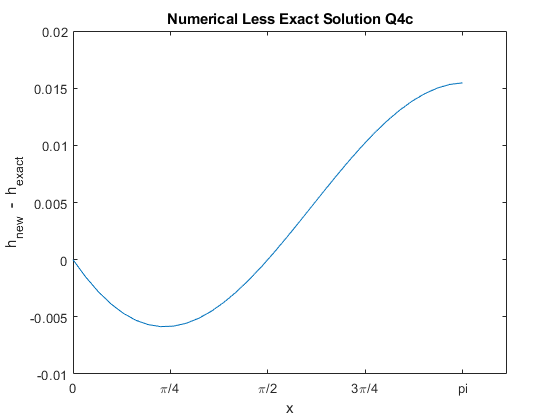


%figure(1)
%plot(xspan,h_new);
%ylabel('h(x)');
%xlabel('x')
%xticks([0, pi/4, pi/2, 3*pi/4 pi])
%xticklabels({'0','\pi/4','\pi/2','3\pi/4','pi'})
figure(1)
plot(xspan,h_new-h_exact);
title('Numerical Less Exact Solution Q4c')
ylabel('h_n_e_w  -  h_e_x_a_c_t');
xlabel('x')
xticks([0, pi/4, pi/2, 3*pi/4 pi])
xticklabels({'0','\pi/4','\pi/2','3\pi/4','pi'})